% Author: Raghav Hariharan
% Based of video content from the Robot Academy
% It is recommended to run this program one section at a time
% Source: https://robotacademy.net.au/masterclass/3d-geometry/?lesson=102
% Please go through the robot academy videos as well!
startup_rvc;

Robotics, Vision & Control: (c) Peter Corke 1992-2020 http://www.petercorke.com
- Robotics Toolbox for MATLAB (release 10.4)
 - ARTE contributed code: 3D models for robot manipulators (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\robot\data\meshes)
 - pHRIWARE (release 1.2): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2024) (c)
- Machine Vision Toolbox for MATLAB (release 4.3)
 - VGG contributed code (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\contrib\vgg)
 - graphseg contributed code (C:\Program Files\MATLAB\R2024a\toolbox\rvctools\contrib\graphseg)
- Spatial Math Toolbox for MATLAB (release 1.0)


## Rotation in 3D

% The orthonormal rotation matricies about x,y,z are:
syms theta

Rotation about x:

Rx = rotx(theta)

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Rotation matrix about y:

Ry = roty(theta)

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Rotation matrix about z:

Notice how this is basicially identical to the 2D rotation matrix. This is because we are rotating about the z axis in a 2D situation

Rz = rotz(theta)

$$Rz = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

We can also plot these on an 3D axis!

R = rotx(pi/2)

R =      1     0     0
     0     0    -1
     0     1     0


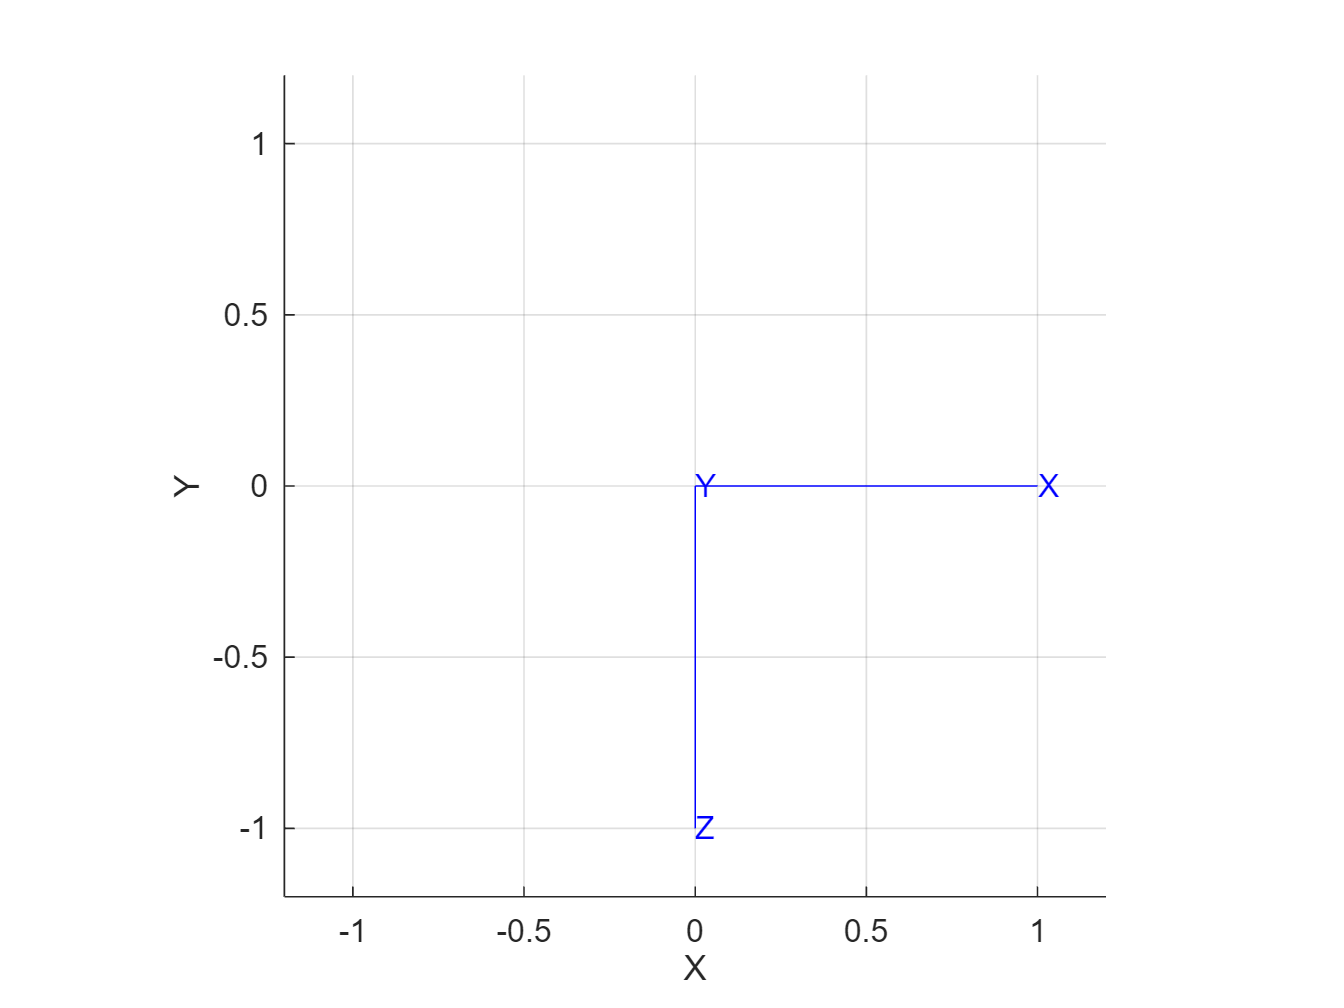


trplot(R) % Notice how in the 2D situation we used trplot2 instead of trplot

The noncommutativity of rotation can be seen below. See how the plot of R1 and R2 are different even though they both contain the same rotations

R1 = rotx(pi/2)*roty(pi/2) % x first then y

R1 =      0     0     1
     1     0     0
     0     1     0



R2 = roty(pi/2)*rotx(pi/2) % y first then x

R2 =      0     1     0
     0     0    -1
    -1     0     0


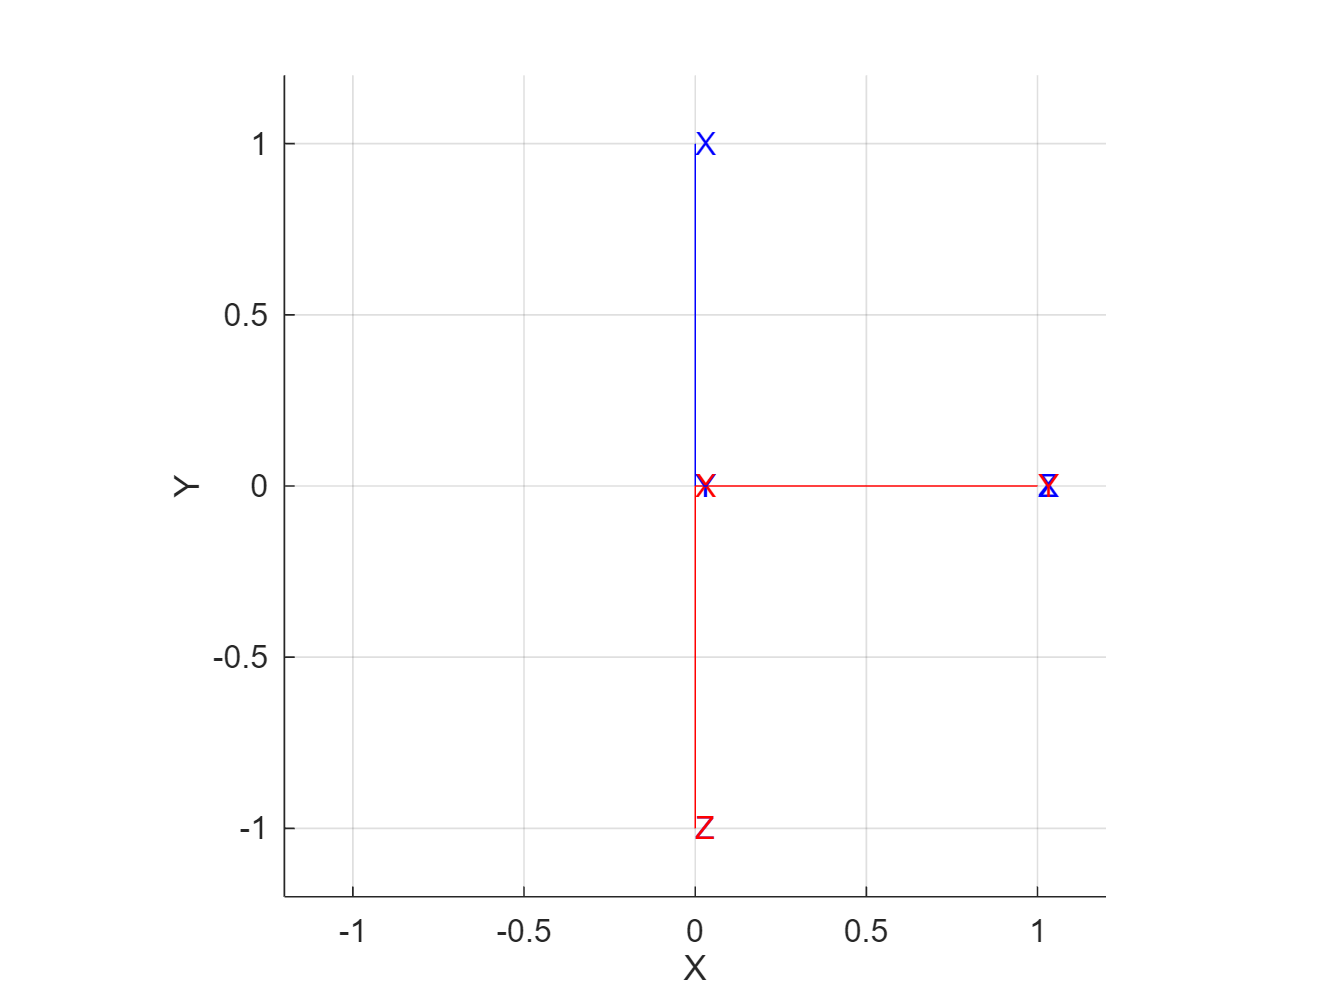


hold on;
trplot(R1, 'color', 'b')
trplot(R2, 'color','r')
hold off;

## Three Angle Representation

Euler's rotation theorm states that any rotation can be represented by not more than 3 rotations about the coordinate axes.

Euler rotations: XYX, XZX, YXY, YZY, ZXZ, or ZYZ

Cardanian Rotations: YZ, XZY, YZX, YXZ, ZXY, or ZYX

It is common practice to refer to all of these three angle rotations as euler rotations

The toolbox defaults to use ZYX which is the roll, pitch, yaw format 

% rpy2r : roll pitch yaw to rotation matrix
R = rpy2r(0.1, 0.2, 0.3)

% rpy2tr: roll pitch yaw to homogenous transformation matrix.
% Remember transformation matrix consists of a rotation matrix and a
% translation matrix
R = rpy2tr(0.1, 0.2, 0.3)